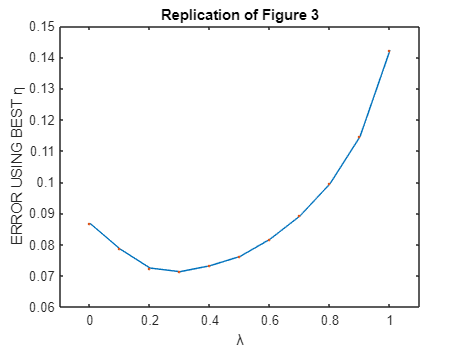

Wexact=([0:6]/6)';
Winitial=[0 0.5 0.5 0.5 0.5 0.5 1]';
RMS=zeros(1,100);
lamlist=[0:0.1:1];
alist=[0:0.05:0.6];
store=zeros(11,13);
store_best=zeros(1,11);
X=diag(ones(1,7));
% Update after training set
tol=0.05;
for chooselam=1:11
    lam=lamlist(chooselam);
for choosea=1:13
    a=alist(choosea);

for set=1:100

Wold=Winitial;
Wnew=Wold;
Wtemp=zeros(7,1);
usetol=tol;
stepfactor=0;

while norm(Wtemp-Wold)>usetol*norm(Wold)
      stepfactor=stepfactor+1;
      usetol=usetol+0.05*fix(stepfactor/1000);
      Wold=Wnew;
      for i=1:10    
         z=zeros(5,1);
         episode=training_sets(i,:,set);
         for j=1:length(episode)
             z=lam*z+X(2:6,episode(j));
             TD=Wold'*( X(:,episode(j+1))-X(:,episode(j)) ); % might be different
             Wnew(2:6)=Wnew(2:6)+0.1*a*TD*z; % changing factor
             if episode(j+1)==7
                 break
             elseif episode(j+1)==1
                 break
             end
         end
      end
      if norm(Wnew-Wexact)>norm(Winitial-Wexact)
          break
      end
      Wtemp=Wnew;
end
RMS(set)=sqrt(mean((Wnew-Wexact).^2));
end
store(chooselam,choosea)=mean(RMS);
end
store_best(chooselam)=min(store(chooselam,:));
end
plot(lamlist,store_best)
hold on
plot(lamlist,store_best,'.')
title('Replication of Figure 3')
xlim([-0.1,1.1])
ylim([0.06,0.15])
xlabel('λ')
ylabel('ERROR USING BEST η')